10deg.txt → 5.805 ± 0.000 cm
15deg.txt → 8.575 ± 0.166 cm


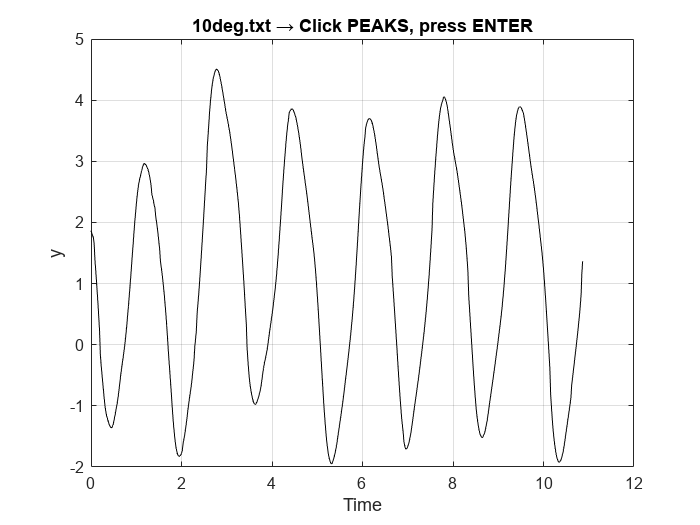

Error using ginput
Interrupted by figure deletion

clear; clc; close all

folder = "data/swimming/amplitude-trim/anguilliform/0.6Hz";
files = dir(fullfile(folder, "*.txt"));

results = [];  % [angle, mean_amp, std_amp]

for k = 1:length(files)

    filename = files(k).name;
    filepath = fullfile(folder, filename);

    % Extract angle from filename (e.g. "20deg")
    angle = sscanf(filename, "%ddeg");

    %% Load data
    data = readmatrix(filepath);
    t = data(:,1);
    y = data(:,3);

    valid = ~isnan(y);
    t = t(valid);
    y = y(valid);

    %% Plot
    figure(1); clf
    plot(t, y, 'k'); grid on; hold on
    title(sprintf('%s → Click PEAKS, press ENTER', filename))
    xlabel('Time'); ylabel('y')

    %% Click peaks
    [xp_click, ~] = ginput;

    window = 20;
    xp = zeros(size(xp_click));
    yp = zeros(size(xp_click));

    for i = 1:length(xp_click)
        [~, idx] = min(abs(t - xp_click(i)));
        i1 = max(1, idx - window);
        i2 = min(length(y), idx + window);
        [yp(i), localIdx] = max(y(i1:i2));
        xp(i) = t(i1 + localIdx - 1);
    end

    plot(xp, yp, 'rv', 'MarkerFaceColor', 'r')

    title('Now click TROUGHS, press ENTER')

    %% Click troughs
    [xt_click, ~] = ginput;

    xt = zeros(size(xt_click));
    yt = zeros(size(xt_click));

    for i = 1:length(xt_click)
        [~, idx] = min(abs(t - xt_click(i)));
        i1 = max(1, idx - window);
        i2 = min(length(y), idx + window);
        [yt(i), localIdx] = min(y(i1:i2));
        xt(i) = t(i1 + localIdx - 1);
    end

    plot(xt, yt, 'b^', 'MarkerFaceColor', 'b')

    %% Amplitude
    n = min(length(yp), length(yt));
    amp = (yp(1:n) - yt(1:n));

    mean_amp = mean(amp);
    std_amp = std(amp);

    fprintf("%s → %.3f ± %.3f cm\n", filename, mean_amp, std_amp);

    results = [results; angle, mean_amp, std_amp];

    pause; % wait before moving to next file
end


%% Sort results by angle
results = sortrows(results, 1);

%% Plot summary
figure;
errorbar(results(:,1), results(:,2), results(:,3), 'o-')
xlabel('Angle (deg)')
ylabel('Amplitude (cm)')
title('Tail amplitude vs angle')
grid on

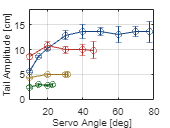

anguilliform_results_0p6 = [10 5.617 0.187 0
                            15 8.575 0.166 1
                            20 10.169 0.302 1
                            30 12.901 0.935 1
                            40 13.663 1.429 1
                            50 13.599 0.814 1
                            60 13.032 1.591 1
                            70 13.707 1.002 1
                            78 13.538 2.089 1];
anguilliform_results_1p0 = [10 8.538 0.513 1
                            20 10.869 0.847 1
                            30 9.961 0.754 1
                            40 9.980 1.104 1
                            46 9.899 1.630 1];
anguilliform_results_1p5 = [10 4.371 0.116 1
                            20 4.956 0.330 1
                            30 4.970 0.401 1
                            31 4.988 0.459 1];
anguilliform_results_2p0 = [10 2.457 0.346 0
                            15 2.896 0.284 0
                            20 2.783 0.244 0
                            23 2.924 0.302 0];

plotW = 6;
plotH = 4.5;

fig = figure;
hold on
errorbar(anguilliform_results_0p6(:,1), anguilliform_results_0p6(:,2), anguilliform_results_0p6(:,3), 'o-')
errorbar(anguilliform_results_1p0(:,1), anguilliform_results_1p0(:,2), anguilliform_results_1p0(:,3), 'o-')
errorbar(anguilliform_results_1p5(:,1), anguilliform_results_1p5(:,2), anguilliform_results_1p5(:,3), 'o-')
errorbar(anguilliform_results_2p0(:,1), anguilliform_results_2p0(:,2), anguilliform_results_2p0(:,3), 'o-')
xlabel('Servo Angle [deg]')
ylabel('Tail Amplitude [cm]')
%legend('0.6 Hz','1 Hz','1.5 Hz','2 Hz',Location='southeast')
grid on
box on

xlim([10 80])
ylim([0 18])

fontsize(10,'points');
colororder('earth')

set(fig, 'Units', 'centimeters', ...
         'Position', [2 2 plotW plotH]);

set(fig, 'PaperUnits', 'centimeters');
set(fig, 'PaperSize', [plotW plotH]);
set(fig, 'PaperPosition', [0 0 plotW plotH]);
set(fig, 'PaperPositionMode', 'manual');

drawnow;

hold off

print(fig, 'anguilliform-amplitude-trim.pdf', '-dpdf', '-vector');

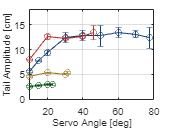

subcarangiform_results_0p6 = [10 5.543 0.172
                          15 7.752 0.152
                          20 9.374 0.461
                          30 12.462 1.007
                          40 12.789 0.987
                          50 12.780 2.092
                          60 13.477 0.967
                          70 13.079 0.702
                          78 12.345 2.141];
subcarangiform_results_1p0 = [10 7.962 0.101
                          20 12.540 0.585
                          30 12.187 0.231
                          40 12.663 0.480
                          46 13.367 1.408];
subcarangiform_results_1p5 = [10 4.539 0.223
                          20 5.312 0.142
                          30 5.073 0.030
                          31 5.360 0.154];
subcarangiform_results_2p0 = [10 2.587 0.285
                          15 2.872 0.187
                          20 2.934 0.173
                          23 3.054 0.193];

plotW = 6;
plotH = 4.5;

fig = figure;
hold on
errorbar(subcarangiform_results_0p6(:,1), subcarangiform_results_0p6(:,2), subcarangiform_results_0p6(:,3), 'o-')
errorbar(subcarangiform_results_1p0(:,1), subcarangiform_results_1p0(:,2), subcarangiform_results_1p0(:,3), 'o-')
errorbar(subcarangiform_results_1p5(:,1), subcarangiform_results_1p5(:,2), subcarangiform_results_1p5(:,3), 'o-')
errorbar(subcarangiform_results_2p0(:,1), subcarangiform_results_2p0(:,2), subcarangiform_results_2p0(:,3), 'o-')
xlabel('Servo Angle [deg]')
ylabel('Tail Amplitude [cm]')
%legend('0.6 Hz','1 Hz','1.5 Hz','2 Hz',Location='southeast')
grid on
box on

xlim([10 80])
ylim([0 18])

fontsize(10,'points');
colororder('earth')

set(fig, 'Units', 'centimeters', ...
         'Position', [2 2 plotW plotH]);

set(fig, 'PaperUnits', 'centimeters');
set(fig, 'PaperSize', [plotW plotH]);
set(fig, 'PaperPosition', [0 0 plotW plotH]);
set(fig, 'PaperPositionMode', 'manual');

drawnow;

hold off

print(fig, 'subcarangiform-amplitude-trim.pdf', '-dpdf', '-vector');

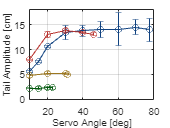

carangiform_results_0p6 = [10 5.636 0.143
                           15 7.602 0.220
                           20 10.625 0.274
                           30 13.453 1.354
                           40 13.739 1.013
                           50 14.074 1.661
                           60 14.126 3.375
                           70 14.537 1.470
                           78 13.990 2.268];
carangiform_results_1p0 = [10 7.918 0.168
                           20 13.062 0.638
                           30 13.866 0.462
                           40 13.448 0.238
                           46 13.114 0.344];
carangiform_results_1p5 = [10 4.705 0.236
                           20 5.293 0.221
                           30 5.214 0.163
                           31 5.092 0.122];
carangiform_results_2p0 = [10 2.279 0.178
                           15 2.252 0.250
                           20 2.359 0.298
                           23 2.350 0.314];

plotW = 6;
plotH = 4.5;

fig = figure;
hold on
errorbar(carangiform_results_0p6(:,1), carangiform_results_0p6(:,2), carangiform_results_0p6(:,3), 'o-')
errorbar(carangiform_results_1p0(:,1), carangiform_results_1p0(:,2), carangiform_results_1p0(:,3), 'o-')
errorbar(carangiform_results_1p5(:,1), carangiform_results_1p5(:,2), carangiform_results_1p5(:,3), 'o-')
errorbar(carangiform_results_2p0(:,1), carangiform_results_2p0(:,2), carangiform_results_2p0(:,3), 'o-')
xlabel('Servo Angle [deg]')
ylabel('Tail Amplitude [cm]')
%legend('0.6 Hz','1 Hz','1.5 Hz','2 Hz',Location='southeast')
grid on
box on

xlim([10 80])
ylim([0 18])

fontsize(10,'points');
colororder('earth')

set(fig, 'Units', 'centimeters', ...
         'Position', [2 2 plotW plotH]);

set(fig, 'PaperUnits', 'centimeters');
set(fig, 'PaperSize', [plotW plotH]);
set(fig, 'PaperPosition', [0 0 plotW plotH]);
set(fig, 'PaperPositionMode', 'manual');

drawnow;

hold off

print(fig, 'carangiform-amplitude-trim.pdf', '-dpdf', '-vector');

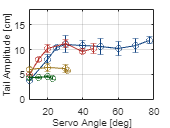

thunniform_results_0p6 = [10 3.847 0.129
                          20 8.069 0.893
                          25 10.472 0.353
                          30 11.107 1.709
                          40 10.902 1.028
                          50 10.588 1.544
                          60 10.273 1.420
                          70 10.834 1.422
                          78 11.919 0.774];
thunniform_results_1p0 = [10 4.956 0.115
                          15 8.057 0.416
                          20 10.235 0.768
                          30 11.229 0.731
                          40 9.707 0.504
                          46 10.286 0.998];
thunniform_results_1p5 = [10 6.028 0.379
                          20 6.391 0.737
                          30 6.135 0.782
                          31 5.717 0.181];
thunniform_results_2p0 = [10 4.320 0.333
                          15 4.342 0.220
                          20 4.617 0.252
                          23 4.285 0.232];

plotW = 6;
plotH = 4.5;

fig = figure;
hold on
errorbar(thunniform_results_0p6(:,1), thunniform_results_0p6(:,2), thunniform_results_0p6(:,3), 'o-')
errorbar(thunniform_results_1p0(:,1), thunniform_results_1p0(:,2), thunniform_results_1p0(:,3), 'o-')
errorbar(thunniform_results_1p5(:,1), thunniform_results_1p5(:,2), thunniform_results_1p5(:,3), 'o-')
errorbar(thunniform_results_2p0(:,1), thunniform_results_2p0(:,2), thunniform_results_2p0(:,3), 'o-')
xlabel('Servo Angle [deg]')
ylabel('Tail Amplitude [cm]')
%legend('0.6 Hz','1 Hz','1.5 Hz','2 Hz',Location='southeast')
grid on
box on

xlim([10 80])
ylim([0 18])

fontsize(10,'points');
colororder('earth')

set(fig, 'Units', 'centimeters', ...
         'Position', [2 2 plotW plotH]);

set(fig, 'PaperUnits', 'centimeters');
set(fig, 'PaperSize', [plotW plotH]);
set(fig, 'PaperPosition', [0 0 plotW plotH]);
set(fig, 'PaperPositionMode', 'manual');

drawnow;

hold off

print(fig, 'thunniform-amplitude-trim.pdf', '-dpdf', '-vector');

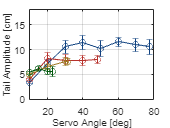

ostraciiform_results_0p6 = [10 3.408 0.175
                            20 7.276 0.658
                            30 10.542 1.340
                            40 11.359 1.380
                            50 10.175 1.655
                            60 11.530 0.938
                            70 10.970 1.273
                            78 10.527 1.595];
ostraciiform_results_1p0 = [10 4.022 0.164
                            20 8.193 1.152
                            30 7.887 1.088
                            40 7.819 0.940
                            48 8.007 0.874];
ostraciiform_results_1p5 = [10 4.927 0.259
                            20 6.561 0.469
                            30 7.643 0.785
                            31 7.581 0.635];
ostraciiform_results_2p0 = [10 5.327 0.248
                            15 6.189 0.374
                            20 5.642 0.655
                            23 5.597 1.019];

plotW = 6;
plotH = 4.5;

fig = figure;
hold on
errorbar(ostraciiform_results_0p6(:,1), ostraciiform_results_0p6(:,2), ostraciiform_results_0p6(:,3), 'o-')
errorbar(ostraciiform_results_1p0(:,1), ostraciiform_results_1p0(:,2), ostraciiform_results_1p0(:,3), 'o-')
errorbar(ostraciiform_results_1p5(:,1), ostraciiform_results_1p5(:,2), ostraciiform_results_1p5(:,3), 'o-')
errorbar(ostraciiform_results_2p0(:,1), ostraciiform_results_2p0(:,2), ostraciiform_results_2p0(:,3), 'o-')
xlabel('Servo Angle [deg]')
ylabel('Tail Amplitude [cm]')
%legend('0.6 Hz','1 Hz','1.5 Hz','2 Hz',Location='southeast')
grid on
box on

xlim([10 80])
ylim([0 18])

fontsize(10,'points');
colororder('earth')

set(fig, 'Units', 'centimeters', ...
         'Position', [2 2 plotW plotH]);

set(fig, 'PaperUnits', 'centimeters');
set(fig, 'PaperSize', [plotW plotH]);
set(fig, 'PaperPosition', [0 0 plotW plotH]);
set(fig, 'PaperPositionMode', 'manual');

drawnow;

hold off

print(fig, 'ostraciiform-amplitude-trim.pdf', '-dpdf', '-vector');

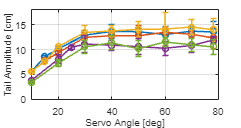

plotW = 8.5;
plotH = 4.5;

fig = figure;
hold on
errorbar(anguilliform_results_0p6(:,1), anguilliform_results_0p6(:,2), anguilliform_results_0p6(:,3), 'o-','LineWidth',1.5)
errorbar(subcarangiform_results_0p6(:,1), subcarangiform_results_0p6(:,2), subcarangiform_results_0p6(:,3), 'o-','LineWidth',1.5)
errorbar(carangiform_results_0p6(:,1), carangiform_results_0p6(:,2), carangiform_results_0p6(:,3), 'o-','LineWidth',1.5)
errorbar(thunniform_results_0p6(:,1), thunniform_results_0p6(:,2), thunniform_results_0p6(:,3), 'o-','LineWidth',1.5)
errorbar(ostraciiform_results_0p6(:,1), ostraciiform_results_0p6(:,2), ostraciiform_results_0p6(:,3), 'o-','LineWidth',1.5)
xlabel('Servo Angle [deg]')
ylabel('Tail Amplitude [cm]')
%legend('0.6 Hz','1 Hz','1.5 Hz','2 Hz',Location='southeast')
grid on
box on

xlim([10 80])
ylim([0 18])

fontsize(10,'points');

set(fig, 'Units', 'centimeters', ...
         'Position', [2 2 plotW plotH]);

set(fig, 'PaperUnits', 'centimeters');
set(fig, 'PaperSize', [plotW plotH]);
set(fig, 'PaperPosition', [0 0 plotW plotH]);
set(fig, 'PaperPositionMode', 'manual');

drawnow;

hold off

print(fig, '0.6hz-amplitude-trim.pdf', '-dpdf', '-vector');

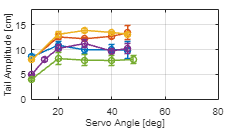

plotW = 8.5;
plotH = 4.5;

fig = figure;
hold on
errorbar(anguilliform_results_1p0(:,1), anguilliform_results_1p0(:,2), anguilliform_results_1p0(:,3), 'o-','LineWidth',1.5)
errorbar(subcarangiform_results_1p0(:,1), subcarangiform_results_1p0(:,2), subcarangiform_results_1p0(:,3), 'o-','LineWidth',1.5)
errorbar(carangiform_results_1p0(:,1), carangiform_results_1p0(:,2), carangiform_results_1p0(:,3), 'o-','LineWidth',1.5)
errorbar(thunniform_results_1p0(:,1), thunniform_results_1p0(:,2), thunniform_results_1p0(:,3), 'o-','LineWidth',1.5)
errorbar(ostraciiform_results_1p0(:,1), ostraciiform_results_1p0(:,2), ostraciiform_results_1p0(:,3), 'o-','LineWidth',1.5)
xlabel('Servo Angle [deg]')
ylabel('Tail Amplitude [cm]')
%legend('0.6 Hz','1 Hz','1.5 Hz','2 Hz',Location='southeast')
grid on
box on

xlim([10 80])
ylim([0 18])

fontsize(10,'points');

set(fig, 'Units', 'centimeters', ...
         'Position', [2 2 plotW plotH]);

set(fig, 'PaperUnits', 'centimeters');
set(fig, 'PaperSize', [plotW plotH]);
set(fig, 'PaperPosition', [0 0 plotW plotH]);
set(fig, 'PaperPositionMode', 'manual');

drawnow;

hold off

print(fig, '1hz-amplitude-trim.pdf', '-dpdf', '-vector');

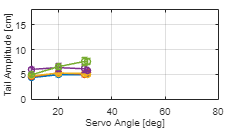

plotW = 8.5;
plotH = 4.5;

fig = figure;
hold on
errorbar(anguilliform_results_1p5(:,1), anguilliform_results_1p5(:,2), anguilliform_results_1p5(:,3), 'o-','LineWidth',1.5)
errorbar(subcarangiform_results_1p5(:,1), subcarangiform_results_1p5(:,2), subcarangiform_results_1p5(:,3), 'o-','LineWidth',1.5)
errorbar(carangiform_results_1p5(:,1), carangiform_results_1p5(:,2), carangiform_results_1p5(:,3), 'o-','LineWidth',1.5)
errorbar(thunniform_results_1p5(:,1), thunniform_results_1p5(:,2), thunniform_results_1p5(:,3), 'o-','LineWidth',1.5)
errorbar(ostraciiform_results_1p5(:,1), ostraciiform_results_1p5(:,2), ostraciiform_results_1p5(:,3), 'o-','LineWidth',1.5)
xlabel('Servo Angle [deg]')
ylabel('Tail Amplitude [cm]')
%legend('0.6 Hz','1 Hz','1.5 Hz','2 Hz',Location='southeast')
grid on
box on

xlim([10 80])
ylim([0 18])

fontsize(10,'points');

set(fig, 'Units', 'centimeters', ...
         'Position', [2 2 plotW plotH]);

set(fig, 'PaperUnits', 'centimeters');
set(fig, 'PaperSize', [plotW plotH]);
set(fig, 'PaperPosition', [0 0 plotW plotH]);
set(fig, 'PaperPositionMode', 'manual');

drawnow;

hold off

print(fig, '1.5hz-amplitude-trim.pdf', '-dpdf', '-vector');

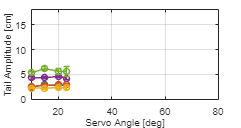

plotW = 8.5;
plotH = 4.5;

fig = figure;
hold on
errorbar(anguilliform_results_2p0(:,1), anguilliform_results_2p0(:,2), anguilliform_results_2p0(:,3), 'o-','LineWidth',1.5)
errorbar(subcarangiform_results_2p0(:,1), subcarangiform_results_2p0(:,2), subcarangiform_results_2p0(:,3), 'o-','LineWidth',1.5)
errorbar(carangiform_results_2p0(:,1), carangiform_results_2p0(:,2), carangiform_results_2p0(:,3), 'o-','LineWidth',1.5)
errorbar(thunniform_results_2p0(:,1), thunniform_results_2p0(:,2), thunniform_results_2p0(:,3), 'o-','LineWidth',1.5)
errorbar(ostraciiform_results_2p0(:,1), ostraciiform_results_2p0(:,2), ostraciiform_results_2p0(:,3), 'o-','LineWidth',1.5)
xlabel('Servo Angle [deg]')
ylabel('Tail Amplitude [cm]')
%legend('0.6 Hz','1 Hz','1.5 Hz','2 Hz',Location='southeast')
grid on
box on

xlim([10 80])
ylim([0 18])

fontsize(10,'points');

set(fig, 'Units', 'centimeters', ...
         'Position', [2 2 plotW plotH]);

set(fig, 'PaperUnits', 'centimeters');
set(fig, 'PaperSize', [plotW plotH]);
set(fig, 'PaperPosition', [0 0 plotW plotH]);
set(fig, 'PaperPositionMode', 'manual');

drawnow;

hold off

print(fig, '2hz-amplitude-trim.pdf', '-dpdf', '-vector');